The Lokta-Volterra model can be modified to use logistic growth, to add a limited carrying capacity to the prey population. The resulting equations become


$$\frac{dx_1}{dt}=a x_1\left(1-\frac{x_1}{K}\right) - b x_1x_2 \\ \frac{dx_2}{dt}=c x_1 x_2 - d x_2 $$


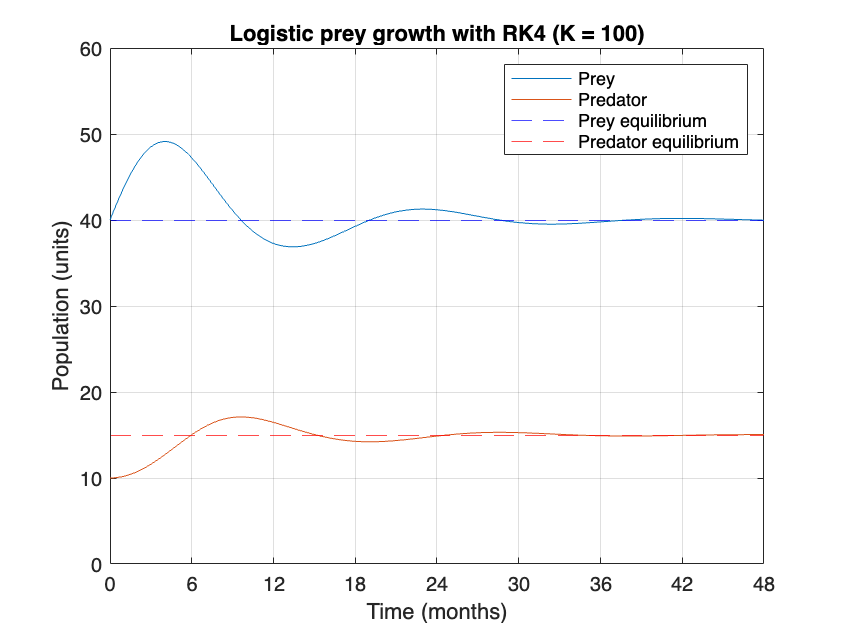

a = 0.5;  % Prey grows by 50% monthly in absence of predators
b = 0.02; % Prey encounters per month per predator
c = 0.01; % Predator efficiency (in converting prey into offspring)
d = 0.4;  % Predator population declines by 40% monthly in absence of prey
K = 100;  % Carrying capacity

prey = 40; predator = 10; n = 1000; t_end = 48;

f = Logistic(a,b,c,d,K);

[t,x] = RungeKutta(f, 0, t_end, [prey; predator], n);

plot(t,x)
grid

yline(d/c, "--",Color="b");
yline(a/b*(1-d/(c*K)), "--",Color="r");
legend("Prey","Predator","Prey equilibrium","Predator equilibrium",location="northeast")
title("Logistic prey growth with RK4 (K = " + K + ")")

xlim([0 48])
ylim([0 60])
xticks(0:6:48)
ylabel("Population (units)")
xlabel("Time (months)")

When a carrying capacity is added into the system, the model will generally converge into the equilibrium points.